clear;
close all;
clc;

%The root directory of the dataset
root_dir=fullfile("p_dataset_26/")

root_dir = "p_dataset_26\"

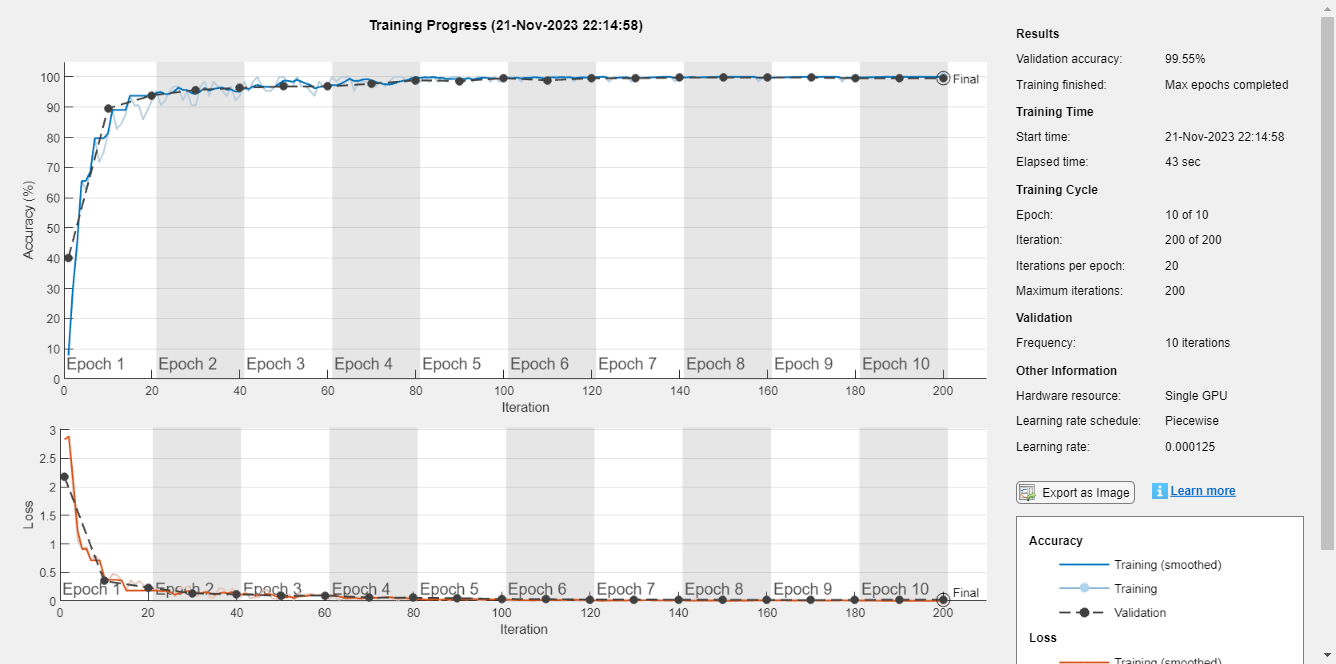

Accuracy of validation set NUM1: 99.5465 %



% Custom function to resize images (For Task 8) 
resizeFcn = @(filename)imresize(imread(filename), [64 64]); %resize to 32,64,256,512
dataset=imageDatastore(root_dir,"IncludeSubfolders",true,"LabelSource","foldernames", "ReadFcn",resizeFcn);


%Determining the size of the images (px px channels) in the dataset
[row_pixels,co_pixels,channels]=size(readimage(dataset,1));

% Dividing the dataset into training set and test (validation) set 
% Training set: test set = 0.75: 0.25
[trainset, testset]=splitEachLabel(dataset,0.75,"randomized");


Layers=[
    imageInputLayer([row_pixels,co_pixels,channels],'Name', 'Input_Layer') 
    
    % First Layer
    convolution2dLayer(3,8,'Padding','same','Name','conv_1')
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1') % Output: 64x64x8

    % Second Layer
    convolution2dLayer(3,16,'Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2') % Output: 32x32x16

    % Third Layer
    convolution2dLayer(3,32,'Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    % No pooling here to preserve spatial dimensions - Output: 32x32x32

    % Fourth Layer
    convolution2dLayer(3,64,'Padding','same','Name','conv_4')
    batchNormalizationLayer('Name','BN_4')
    reluLayer('Name','relu_4')
    averagePooling2dLayer(2,"Stride",2,"Name","avg_pool_1") % Output: 16x16x64

    % 5th Layer
    convolution2dLayer(3,128,'Padding','same','Name','conv_5')
    batchNormalizationLayer('Name','BN_5')
    reluLayer('Name','relu_5')
    % No pooling here - Output: 16x16x128

    % 6th Layer
    convolution2dLayer(3,128,'Padding','same','Name','conv_6')
    batchNormalizationLayer('Name','BN_6')
    reluLayer('Name','relu_6')
    % Reduced pooling stride - Output: 8x8x128
    averagePooling2dLayer(2,"Stride",1,"Name","avg_pool_2") 

    % 7th Layer
    convolution2dLayer(3,256,'Padding','same','Name','conv_7') % Add padding
    batchNormalizationLayer('Name','BN_7')
    reluLayer('Name','relu_7')
    averagePooling2dLayer(2,"Stride",2,"Name","avg_pool_3") % Output: 4x4x256

    dropoutLayer

    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer
];




options = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ...       % Initially tested at 0.01
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',3, ...        %Initially tested at 2
    'LearnRateDropFactor',0.5, ...
    'MaxEpochs',10,...                  % Initially tested at 15
    'Shuffle','every-epoch', ...
    'ValidationData',testset, ...
    'ValidationFrequency',10, ...   
    'MiniBatchSize',64, ...
    'Verbose',false, ...
    'ExecutionEnvironment','gpu', ...
    'Plots','training-progress');




% Testing and displaying accuracy of model on validation set 10 times 
accuracy_save = zeros(1, 10);
for i = 1
    net = trainNetwork(trainset, Layers, options);
    predictions = classify(net, testset);
    actual_labels = testset.Labels;
    accuracy = sum(predictions == actual_labels) / numel(actual_labels) * 100;
    accuracy_save(i) = accuracy;
    disp(['Accuracy of validation set NUM', num2str(i), ': ', num2str(accuracy), ' %']);
end


% Calculate and display the final average accuracy
final_avg_accuracy = mean(accuracy_save);
disp(['Final average accuracy: ', num2str(final_avg_accuracy), ' %']);

Final average accuracy: 9.9546 %


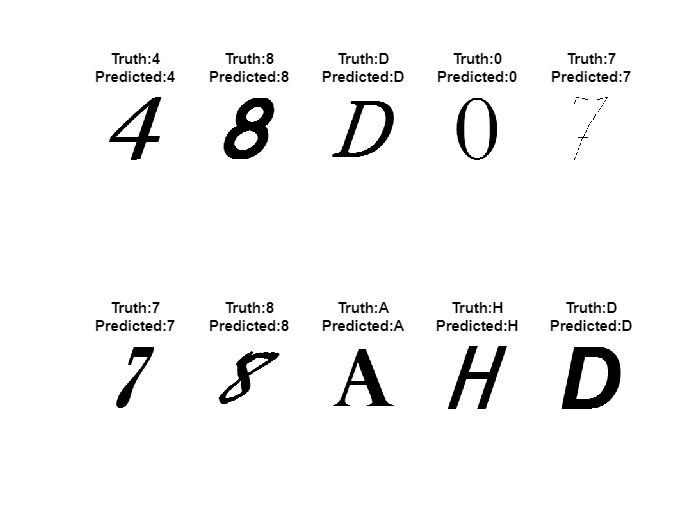


% Save the accuracies
save('accuracy_saving.mat', 'accuracy_save', 'final_avg_accuracy')

% Predicted Labels vs Actual Labels
random_num = randperm(numel(predictions), 10);
figure;
for i = 1:10
    subplot(2, 5, i);
    imshow(testset.Files{random_num(i)});
    title({['Truth:' char(actual_labels(random_num(i)))],['Predicted:' char(predictions(random_num(i)))]});
end

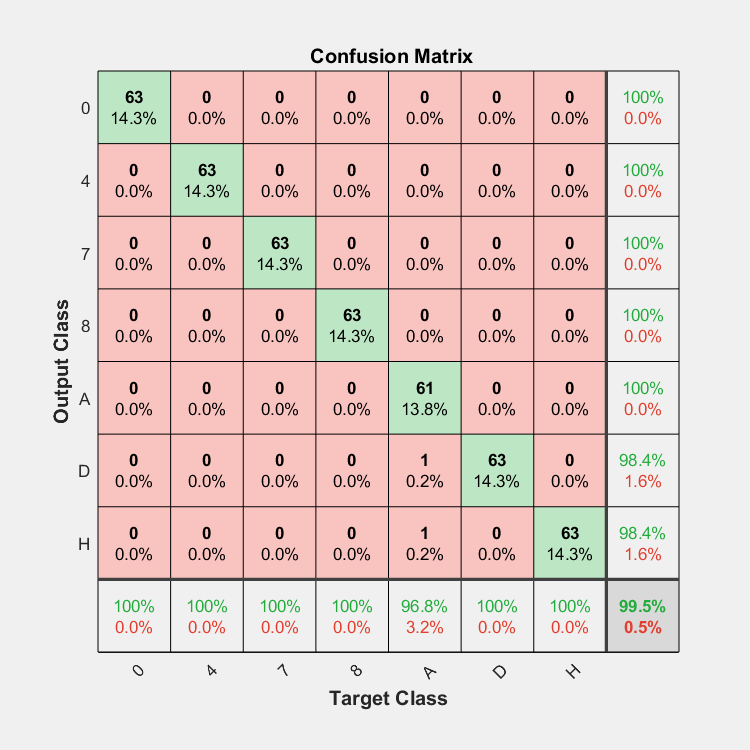


% Confusion matrix for evaluating the performance 
figure;
plotconfusion(actual_labels, predictions);

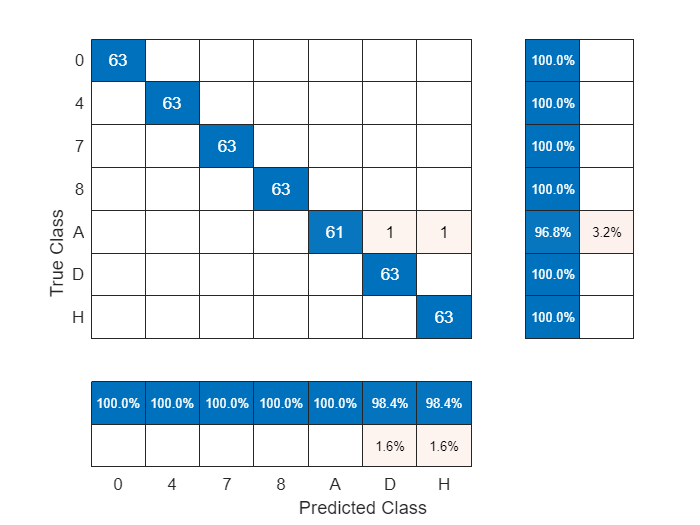


% Confusion chart for evaluating the performance 
figure;
chart = confusionchart(actual_labels, predictions, 'RowSummary','row-normalized','ColumnSummary','column-normalized');


% Saving CNN 
% CNN_resized_32 = net; %change the folder name depending on resize [32,64,256,512]
% save CNN_resized_32